# Winner-take-all

clear;
clc;
addpath('../funcs');
load ../../data/all4000_withAttn_0_0.5_0_0.05_Iattn_0.02.mat;
filepath = '../../paper/figure4/';
condition = {'Original', 'Condition: S1', 'Condition: S2','Condition: S1S2','Condition: S1S2+A1','Condition: S1S2+A2'};

solidAlpha = 1*256;
dashAlpha = 1*256;
solidColors = [[127 88 175 solidAlpha]; [100 197 235 solidAlpha]; [232 77 138 solidAlpha]; [254 179 38 solidAlpha]]/256;
dashColors = [[127 88 175 dashAlpha]; [100 197 235 dashAlpha]; [232 77 138 dashAlpha]; [254 179 38 dashAlpha]]/256;
dotColors = [[127 88 175]; [100 197 235]; [232 77 138]; [254 179 38]]/256;

Delta_e_start = 0; % cannot equal to 0
Delta_e_end = 0.5; % can equal to 0.5
Delta_e_steps = 200;

Delta_i_start = 0; % cannot equal to 0
Delta_i_end = 0.05; % can equal to 0.05
Delta_i_steps = 200;

Iattn = 0.02;
time = 9000;
stimIn = 5000;

dt = 0.01;
timeax = 0:dt:time;
timeax = timeax'/1000;

stimDur = time - stimIn;
step_stimIn = stimIn/dt;
step_stim = stimDur/dt;

## Time-course: circle only attn, not using

Delta_E = 0.12;
Delta_I = 0.04;

[r,~,~] = onlyAttn(Delta_E, Delta_I, Iattn, time);
r = r*1000;

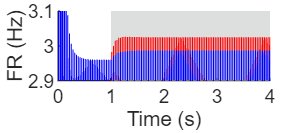

pop = 1;
figure();

hold on;
 
recX = [1 4 4 1];
recY = [0 0 5 5];
r1 = fill(recX, recY, 0.9*[209 211 212]/256,'LineStyle','none');
alpha(r1,0.5);

plot(timeax,squeeze(r(pop,:,4)),'r','LineWidth',0.3);
% hold on;
plot(timeax,squeeze(r(pop,:,5)),'b','LineWidth',0.3);


hold off;
axis([0 4 2.9 3.1]);
xlabel("Time (s)");
ylabel("FR (Hz)");
xticks([0 1 2 3 4]);

x0 = 0; y0 = 0; width = 4.5; height = 2;
set(gcf,'units','centimeters','position',[x0,y0,width,height]);
set(gca, 'FontName', 'Arial');
set(gca,'FontSize',8);

% filename = append(filepath,'tc_circle_only');
% print(filename, '-dpng', '-r600');
% print(filename, '-dsvg', '-r600');

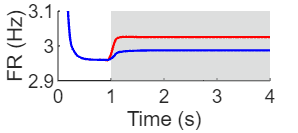

figure();

hold on;

recX = [1 4 4 1];
recY = [0 0 5 5];
r1 = fill(recX, recY, 0.9*[209 211 212]/256,'LineStyle','none');
alpha(r1,0.5);

envMthd = 'peak';
envWdo = 4000;
[cond4BF, ] = envelope(squeeze(r(pop,1:step_stimIn,4)),envWdo,envMthd);
[cond5BF, ] = envelope(squeeze(r(pop,1:step_stimIn,5)),envWdo,envMthd);

[cond4AF, ] = envelope(squeeze(r(pop,step_stimIn+1:step_stimIn+step_stim+1,4)),envWdo,envMthd);
[cond5AF, ] = envelope(squeeze(r(pop,step_stimIn+1:step_stimIn+step_stim+1,5)),envWdo,envMthd);

cond4 = cat(2, cond4BF, cond4AF);
cond5 = cat(2, cond5BF, cond5AF);

plot(timeax,cond4,'r','LineWidth',1);
plot(timeax,cond5,'b','LineWidth',1);

hold off;
axis([0 4 2.9 3.1]);
xlabel("Time (s)");
ylabel("FR (Hz)");
xticks([0 1 2 3 4]);

x0 = 0; y0 = 0; width = 4.5; height = 2;
set(gcf,'units','centimeters','position',[x0,y0,width,height]);
set(gca, 'FontName', 'Arial');
set(gca,'FontSize',8);

% filename = append(filepath,'tc_circle_only_env');
% print(filename, '-dpng', '-r600');
% print(filename, '-dsvg', '-r600');

## Time-course: circle sens+attn

Delta_E = 0.12;
Delta_I = 0.04;

[r,~,~] = once(Delta_E, Delta_I, Iattn, time, stimIn);
r = r*1000;

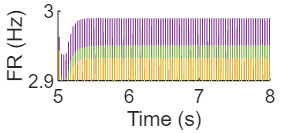

pop = 1;
figure();

hold on;
 
% recX = [1 4 4 1];
% recY = [0 0 5 5];
% r1 = fill(recX, recY, 0.9*[209 211 212]/256,'LineStyle','none');
% alpha(r1,0.5);

% plot(timeax,squeeze(r(pop,:,4)),'r','LineWidth',0.3);
% plot(timeax,squeeze(r(pop,:,5)),'b','LineWidth',0.3);

% plot(timeax,squeeze(r(pop,:,1)),'Color','#0072BD','LineWidth',0.3);
plot(timeax,squeeze(r(pop,:,4)),'Color','#7E2F8E','LineWidth',0.3);
plot(timeax,squeeze(r(pop,:,5)),'Color','#77AC30','LineWidth',0.3);
plot(timeax,squeeze(r(pop,:,3)),'Color','#EDB120','LineWidth',0.3);
% plot(timeax,squeeze(r(pop,:,2)),'Color','#D95319','LineWidth',0.3);

hold off;
axis([stimIn/1000 (time-1000)/1000 2.9 3]);
xlabel("Time (s)");
ylabel("FR (Hz)");
yticks([2.9 3]);
xticks([5 6 7 8]);

x0 = 0; y0 = 0; width = 4.5; height = 2;
set(gcf,'units','centimeters','position',[x0,y0,width,height]);
set(gca, 'FontName', 'Arial');
set(gca,'FontSize',8);
filename = append(filepath,'tc_circle_L23E');
print(filename, '-dpng', '-r600');
print(filename, '-dsvg', '-r600');

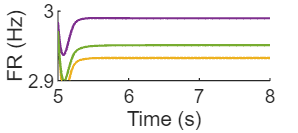

figure();

hold on;

% recX = [1 4 4 1];
% recY = [0 0 5 5];
% r1 = fill(recX, recY, 0.9*[209 211 212]/256,'LineStyle','none');
% alpha(r1,0.5);

envMthd = 'peak';
envWdo = 4000;
% [cond4BF, ] = envelope(squeeze(r(pop,1:step_stimIn,4)),envWdo,envMthd);
% [cond5BF, ] = envelope(squeeze(r(pop,1:step_stimIn,5)),envWdo,envMthd);
% 
% [cond4AF, ] = envelope(squeeze(r(pop,step_stimIn+1:step_stimIn+step_stim+1,4)),envWdo,envMthd);
% [cond5AF, ] = envelope(squeeze(r(pop,step_stimIn+1:step_stimIn+step_stim+1,5)),envWdo,envMthd);
% 
% cond4 = cat(2, cond4BF, cond4AF);
% cond5 = cat(2, cond5BF, cond5AF);
% 
% plot(timeax,cond4,'r','LineWidth',1);
% plot(timeax,cond5,'b','LineWidth',1);

[cond1BF, ] = envelope(squeeze(r(pop,1:step_stimIn,1)),envWdo,envMthd);
[cond2BF, ] = envelope(squeeze(r(pop,1:step_stimIn,2)),envWdo,envMthd);
[cond3BF, ] = envelope(squeeze(r(pop,1:step_stimIn,3)),envWdo,envMthd);
[cond4BF, ] = envelope(squeeze(r(pop,1:step_stimIn,4)),envWdo,envMthd);
[cond5BF, ] = envelope(squeeze(r(pop,1:step_stimIn,5)),envWdo,envMthd);

[cond1AF, ] = envelope(squeeze(r(pop,step_stimIn+1:step_stimIn+step_stim+1,1)),envWdo,envMthd);
[cond2AF, ] = envelope(squeeze(r(pop,step_stimIn+1:step_stimIn+step_stim+1,2)),envWdo,envMthd);
[cond3AF, ] = envelope(squeeze(r(pop,step_stimIn+1:step_stimIn+step_stim+1,3)),envWdo,envMthd);
[cond4AF, ] = envelope(squeeze(r(pop,step_stimIn+1:step_stimIn+step_stim+1,4)),envWdo,envMthd);
[cond5AF, ] = envelope(squeeze(r(pop,step_stimIn+1:step_stimIn+step_stim+1,5)),envWdo,envMthd);

cond1 = cat(2, cond1BF, cond1AF);
cond2 = cat(2, cond2BF, cond2AF);
cond3 = cat(2, cond3BF, cond3AF);
cond4 = cat(2, cond4BF, cond4AF);
cond5 = cat(2, cond5BF, cond5AF);

% plot(timeax,cond1,'Color','#0072BD','LineWidth',1);
plot(timeax,cond3,'Color','#EDB120','LineWidth',1);
plot(timeax,cond4,'Color','#7E2F8E','LineWidth',1);
plot(timeax,cond5,'Color','#77AC30','LineWidth',1);
% plot(timeax,cond2,'Color','#D95319','LineWidth',1);

hold off;
axis([stimIn/1000 (time-1000)/1000 2.9 3]);
xlabel("Time (s)");
ylabel("FR (Hz)");
yticks([2.9 3]);
xticks([5 6 7 8]);

x0 = 0; y0 = 0; width = 4.5; height = 2;
set(gcf,'units','centimeters','position',[x0,y0,width,height]);
set(gca, 'FontName', 'Arial');
set(gca,'FontSize',8);
filename = append(filepath,'tc_circle_L23E_env');
print(filename, '-dpng', '-r600');
print(filename, '-dsvg', '-r600');

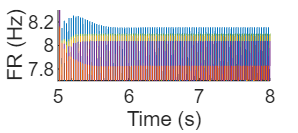

pop = 5;
figure();

hold on;
 
% recX = [1 4 4 1];
% recY = [0 0 200 200];
% r1 = fill(recX, recY, 0.9*[209 211 212]/256,'LineStyle','none');
% alpha(r1,0.5);

plot(timeax,squeeze(r(pop,:,1)),'Color','#0072BD','LineWidth',0.3);
plot(timeax,squeeze(r(pop,:,5)),'Color','#77AC30','LineWidth',0.3);
plot(timeax,squeeze(r(pop,:,3)),'Color','#EDB120','LineWidth',0.3);
plot(timeax,squeeze(r(pop,:,4)),'Color','#7E2F8E','LineWidth',0.3);
plot(timeax,squeeze(r(pop,:,2)),'Color','#D95319','LineWidth',0.3);

hold off;
axis([stimIn/1000 (time-1000)/1000 7.7 8.3]);
xlabel("Time (s)");
ylabel("FR (Hz)");
% yticks([2.9 3]);
xticks([5 6 7 8]);

x0 = 0; y0 = 0; width = 4.5; height = 2;
set(gcf,'units','centimeters','position',[x0,y0,width,height]);
set(gca, 'FontName', 'Arial');
set(gca,'FontSize',8);
filename = append(filepath,'tc_circle_L5E');
print(filename, '-dpng', '-r600');
print(filename, '-dsvg', '-r600');

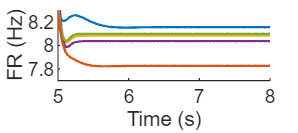

figure();

hold on;

recX = [1 4 4 1];
recY = [0 0 200 200];
r1 = fill(recX, recY, 0.9*[209 211 212]/256,'LineStyle','none');
alpha(r1,0.5);

envMthd = 'peak';
envWdo = 4000;
[cond1BF, ] = envelope(squeeze(r(pop,1:step_stimIn,1)),envWdo,envMthd);
[cond2BF, ] = envelope(squeeze(r(pop,1:step_stimIn,2)),envWdo,envMthd);
[cond3BF, ] = envelope(squeeze(r(pop,1:step_stimIn,3)),envWdo,envMthd);
[cond4BF, ] = envelope(squeeze(r(pop,1:step_stimIn,4)),envWdo,envMthd);
[cond5BF, ] = envelope(squeeze(r(pop,1:step_stimIn,5)),envWdo,envMthd);

[cond1AF, ] = envelope(squeeze(r(pop,step_stimIn+1:step_stimIn+step_stim+1,1)),envWdo,envMthd);
[cond2AF, ] = envelope(squeeze(r(pop,step_stimIn+1:step_stimIn+step_stim+1,2)),envWdo,envMthd);
[cond3AF, ] = envelope(squeeze(r(pop,step_stimIn+1:step_stimIn+step_stim+1,3)),envWdo,envMthd);
[cond4AF, ] = envelope(squeeze(r(pop,step_stimIn+1:step_stimIn+step_stim+1,4)),envWdo,envMthd);
[cond5AF, ] = envelope(squeeze(r(pop,step_stimIn+1:step_stimIn+step_stim+1,5)),envWdo,envMthd);

cond1 = cat(2, cond1BF, cond1AF);
cond2 = cat(2, cond2BF, cond2AF);
cond3 = cat(2, cond3BF, cond3AF);
cond4 = cat(2, cond4BF, cond4AF);
cond5 = cat(2, cond5BF, cond5AF);

plot(timeax,cond1,'Color','#0072BD','LineWidth',1);
plot(timeax,cond3,'Color','#EDB120','LineWidth',1);
plot(timeax,cond4,'Color','#7E2F8E','LineWidth',1);
plot(timeax,cond5,'Color','#77AC30','LineWidth',1);
plot(timeax,cond2,'Color','#D95319','LineWidth',1);

hold off;
axis([stimIn/1000 (time-1000)/1000 7.7 8.3]);
xlabel("Time (s)");
ylabel("FR (Hz)");
% yticks([2.9 3]);
xticks([5 6 7 8]);

x0 = 0; y0 = 0; width = 4.5; height = 2;
set(gcf,'units','centimeters','position',[x0,y0,width,height]);
set(gca, 'FontName', 'Arial');
set(gca,'FontSize',8);
filename = append(filepath,'tc_circle_L5E_env');
print(filename, '-dpng', '-r600');
print(filename, '-dsvg', '-r600');

## Line chart: circle

% figure();
% [~,~,~,~,~,level,~] = record(r/1000, time);
% level_norm = normBetween01(level,2);
% condax = [0 1 2 3 4 5];
% for layer = 1:4
%     pop_E = (layer-1)*2 + 1;
%     pop_I = layer*2;
% 
%     plot(condax, level_norm(pop_E,:),'Color',solidColors(layer,:), 'LineWidth',1);
%     hold on;
%     plot(condax, level_norm(pop_I,:),":",'Color',dashColors(layer,:), 'LineWidth',1);
% 
% end
% 
% ylabel("Normalized firing rate");
% % xlabel("Conditions");
% xlim([0 5]);
% xticks([0 1 2 3 4 5]);
% xticklabels(["original" "S1" "S2" "S1S2" "S1S2+A1" "S1S2+A2"]);
% ylim([0 1]);
% yticks([0 1]);
% yticklabels(["Min" "Max"]);
% 
% x0 = 0; y0 = 0; width = 4.5; height = 4.5;
% set(gcf,'units','centimeters','position',[x0,y0,width,height]);
% set(gca, 'FontName', 'Arial');
% set(gca,'FontSize',8);
% 
% filename = append(filepath,'tc_circle_lChart');
% print(filename, '-dpng', '-r600');
% print(filename, '-dsvg', '-r600');

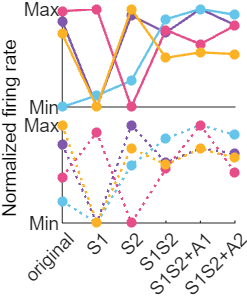

filepath = '../../paper/figure5/';
dot_size = 15;
figure();
[~,~,~,~,~,level,~] = record(r/1000, time);
level_norm = normBetween01(level,2);
condax = [0 1 2 3 4 5];

% Create a subplot for the upper half
subplot(2, 1, 1); 
hold on;
for layer = 1:4
    pop_E = (layer-1)*2 + 1;
    plot(condax, level_norm(pop_E,:),'Color',solidColors(layer,:), 'LineWidth',1);
    scatter(condax, level_norm(pop_E,:), dot_size,...
        'MarkerEdgeColor', dotColors(layer,:), 'MarkerFaceColor',dotColors(layer,:));
end
xlim([0 5]);
xticks([]); % No xticks for the upper plot
ylim([0 1]);
yticks([0 1]);
yticklabels(["Min" "Max"]);
set(gca, 'FontName', 'Arial');
set(gca,'FontSize',8);
set(gca, 'Position', [0.25 0.64 0.7 0.33]); % Adjust the position manually

% Create a subplot for the lower half
subplot(2, 1, 2); 
hold on;
for layer = 1:4
    pop_I = layer*2;
    plot(condax, level_norm(pop_I,:),":",'Color',dashColors(layer,:), 'LineWidth',1);
    scatter(condax, level_norm(pop_I,:), dot_size,...
        'MarkerEdgeColor', dotColors(layer,:), 'MarkerFaceColor',dotColors(layer,:));
end
xlabel("Conditions");
xlim([0 5]);
xticks([0 1 2 3 4 5]);
xticklabels(["original" "S1" "S2" "S1S2" "S1S2+A1" "S1S2+A2"]);
ylim([0 1]);
yticks([0 1]);
yticklabels(["Min" "Max"]);
set(gca, 'FontName', 'Arial');
set(gca,'FontSize',8);
set(gca, 'Position', [0.25 0.25 0.7 0.33]); % Adjust the position manually

% Add y label to the figure using annotation
annotation('textbox', [0.2, 0.2, 0.9, 0.2], 'String', 'Normalized firing rate',...
    'HorizontalAlignment', 'center', 'Rotation', 90, 'FontSize', 8, 'FontName', 'Arial',...
    'EdgeColor', 'none');

x0 = 0; y0 = 0; width = 4.5*(106/128); height = 4.5;
set(gcf,'units','centimeters','position',[x0,y0,width,height]);
set(gca, 'FontName', 'Arial');
set(gca,'FontSize',8);

filename = append(filepath,'tc_circle_lChart');
print(filename, '-dpng', '-r600');
print(filename, '-dsvg', '-r600');

## Time-course: plus

Delta_E = 0.08;
Delta_I = 0.02;

[r,~,~] = once(Delta_E, Delta_I, Iattn, time, stimIn);
r = r*1000;

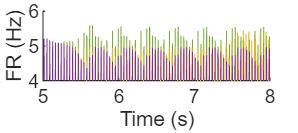

filepath = '../../paper/figure4/';
pop = 1;
figure();

hold on;
 
% recX = [1 4 4 1];
% recY = [0 0 200 200];
% r1 = fill(recX, recY, 0.9*[209 211 212]/256,'LineStyle','none');
% alpha(r1,0.5);

% plot(timeax,squeeze(r(pop,:,5)),'b','LineWidth',0.3);
% plot(timeax,squeeze(r(pop,:,4)),'r','LineWidth',0.3);

plot(timeax,squeeze(r(pop,:,5)),'Color','#77AC30','LineWidth',0.3);
plot(timeax,squeeze(r(pop,:,3)),'Color','#EDB120','LineWidth',0.3);
plot(timeax,squeeze(r(pop,:,4)),'Color','#7E2F8E','LineWidth',0.3);

hold off;
axis([stimIn/1000 (time-1000)/1000 4 6]);
xlabel("Time (s)");
ylabel("FR (Hz)");
% yticks([2.9 3]);
xticks([5 6 7 8]);


x0 = 0; y0 = 0; width = 4.5; height = 2;
set(gcf,'units','centimeters','position',[x0,y0,width,height]);
set(gca, 'FontName', 'Arial');
set(gca,'FontSize',8);
filename = append(filepath,'tc_plus_L23E');
print(filename, '-dpng', '-r600');
print(filename, '-dsvg', '-r600');

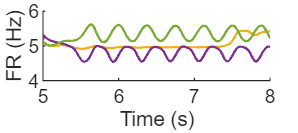

figure();

hold on;

% recX = [1 4 4 1];
% recY = [0 0 200 200];
% r1 = fill(recX, recY, 0.9*[209 211 212]/256,'LineStyle','none');
% alpha(r1,0.5);

envMthd = 'peak';
envWdo = 4000;
% [cond4BF, ] = envelope(squeeze(r(pop,1:step_stimIn,4)),envWdo,envMthd);
% [cond5BF, ] = envelope(squeeze(r(pop,1:step_stimIn,5)),envWdo,envMthd);
% 
% [cond4AF, ] = envelope(squeeze(r(pop,step_stimIn+1:step_stimIn+step_stim+1,4)),envWdo,envMthd);
% [cond5AF, ] = envelope(squeeze(r(pop,step_stimIn+1:step_stimIn+step_stim+1,5)),envWdo,envMthd);
% 
% cond4 = cat(2, cond4BF, cond4AF);
% cond5 = cat(2, cond5BF, cond5AF);

[cond1BF, ] = envelope(squeeze(r(pop,1:step_stimIn,1)),envWdo,envMthd);
[cond2BF, ] = envelope(squeeze(r(pop,1:step_stimIn,2)),envWdo,envMthd);
[cond3BF, ] = envelope(squeeze(r(pop,1:step_stimIn,3)),envWdo,envMthd);
[cond4BF, ] = envelope(squeeze(r(pop,1:step_stimIn,4)),envWdo,envMthd);
[cond5BF, ] = envelope(squeeze(r(pop,1:step_stimIn,5)),envWdo,envMthd);

[cond1AF, ] = envelope(squeeze(r(pop,step_stimIn+1:step_stimIn+step_stim+1,1)),envWdo,envMthd);
[cond2AF, ] = envelope(squeeze(r(pop,step_stimIn+1:step_stimIn+step_stim+1,2)),envWdo,envMthd);
[cond3AF, ] = envelope(squeeze(r(pop,step_stimIn+1:step_stimIn+step_stim+1,3)),envWdo,envMthd);
[cond4AF, ] = envelope(squeeze(r(pop,step_stimIn+1:step_stimIn+step_stim+1,4)),envWdo,envMthd);
[cond5AF, ] = envelope(squeeze(r(pop,step_stimIn+1:step_stimIn+step_stim+1,5)),envWdo,envMthd);

cond1 = cat(2, cond1BF, cond1AF);
cond2 = cat(2, cond2BF, cond2AF);
cond3 = cat(2, cond3BF, cond3AF);
cond4 = cat(2, cond4BF, cond4AF);
cond5 = cat(2, cond5BF, cond5AF);


plot(timeax,cond3,'Color','#EDB120','LineWidth',1);
plot(timeax,cond4,'Color','#7E2F8E','LineWidth',1);
plot(timeax,cond5,'Color','#77AC30','LineWidth',1);

hold off;
axis([stimIn/1000 (time-1000)/1000 4 6]);
xlabel("Time (s)");
ylabel("FR (Hz)");
% yticks([2.9 3]);
xticks([5 6 7 8]);

x0 = 0; y0 = 0; width = 4.5; height = 2;
set(gcf,'units','centimeters','position',[x0,y0,width,height]);
set(gca, 'FontName', 'Arial');
set(gca,'FontSize',8);
filename = append(filepath,'tc_plus_L23E_env');
print(filename, '-dpng', '-r600');
print(filename, '-dsvg', '-r600');

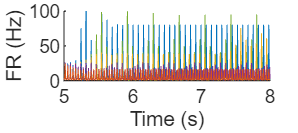

pop = 5;
figure();

hold on;
 
% recX = [1 4 4 1];
% recY = [0 0 200 200];
% r1 = fill(recX, recY, 0.9*[209 211 212]/256,'LineStyle','none');
% alpha(r1,0.5);

plot(timeax,squeeze(r(pop,:,1)),'Color','#0072BD','LineWidth',0.3);
plot(timeax,squeeze(r(pop,:,5)),'Color','#77AC30','LineWidth',0.3);
plot(timeax,squeeze(r(pop,:,3)),'Color','#EDB120','LineWidth',0.3);
plot(timeax,squeeze(r(pop,:,4)),'Color','#7E2F8E','LineWidth',0.3);
plot(timeax,squeeze(r(pop,:,2)),'Color','#D95319','LineWidth',0.3);

hold off;
axis([stimIn/1000 (time-1000)/1000 0 100]);
xlabel("Time (s)");
ylabel("FR (Hz)");
xticks([5 6 7 8]);

x0 = 0; y0 = 0; width = 4.5; height = 2;
set(gcf,'units','centimeters','position',[x0,y0,width,height]);
set(gca, 'FontName', 'Arial');
set(gca,'FontSize',8);
filename = append(filepath,'tc_plus_L5E');
print(filename, '-dpng', '-r600');
print(filename, '-dsvg', '-r600');

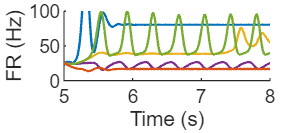

figure();

hold on;

% recX = [1 4 4 1];
% recY = [0 0 200 200];
% r1 = fill(recX, recY, 0.9*[209 211 212]/256,'LineStyle','none');
% alpha(r1,0.5);

envMthd = 'peak';
envWdo = 4000;
[cond1BF, ] = envelope(squeeze(r(pop,1:step_stimIn,1)),envWdo,envMthd);
[cond2BF, ] = envelope(squeeze(r(pop,1:step_stimIn,2)),envWdo,envMthd);
[cond3BF, ] = envelope(squeeze(r(pop,1:step_stimIn,3)),envWdo,envMthd);
[cond4BF, ] = envelope(squeeze(r(pop,1:step_stimIn,4)),envWdo,envMthd);
[cond5BF, ] = envelope(squeeze(r(pop,1:step_stimIn,5)),envWdo,envMthd);

[cond1AF, ] = envelope(squeeze(r(pop,step_stimIn+1:step_stimIn+step_stim+1,1)),envWdo,envMthd);
[cond2AF, ] = envelope(squeeze(r(pop,step_stimIn+1:step_stimIn+step_stim+1,2)),envWdo,envMthd);
[cond3AF, ] = envelope(squeeze(r(pop,step_stimIn+1:step_stimIn+step_stim+1,3)),envWdo,envMthd);
[cond4AF, ] = envelope(squeeze(r(pop,step_stimIn+1:step_stimIn+step_stim+1,4)),envWdo,envMthd);
[cond5AF, ] = envelope(squeeze(r(pop,step_stimIn+1:step_stimIn+step_stim+1,5)),envWdo,envMthd);

cond1 = cat(2, cond1BF, cond1AF);
cond2 = cat(2, cond2BF, cond2AF);
cond3 = cat(2, cond3BF, cond3AF);
cond4 = cat(2, cond4BF, cond4AF);
cond5 = cat(2, cond5BF, cond5AF);

plot(timeax,cond1,'Color','#0072BD','LineWidth',1);
plot(timeax,cond3,'Color','#EDB120','LineWidth',1);
plot(timeax,cond4,'Color','#7E2F8E','LineWidth',1);
plot(timeax,cond5,'Color','#77AC30','LineWidth',1);
plot(timeax,cond2,'Color','#D95319','LineWidth',1);

hold off;
axis([stimIn/1000 (time-1000)/1000 0 100]);
xlabel("Time (s)");
ylabel("FR (Hz)");
xticks([5 6 7 8]);

x0 = 0; y0 = 0; width = 4.5; height = 2;
set(gcf,'units','centimeters','position',[x0,y0,width,height]);
set(gca, 'FontName', 'Arial');
set(gca,'FontSize',8);
filename = append(filepath,'tc_plus_L5E_env');
print(filename, '-dpng', '-r600');
print(filename, '-dsvg', '-r600');

## Line chart: plus

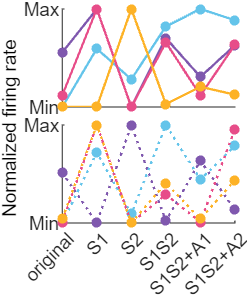

filepath = '../../paper/figure5/';
figure();
[~,~,~,~,~,level,~] = record(r/1000, time);
level_norm = normBetween01(level,2);
condax = [0 1 2 3 4 5];
dot_size = 15;

% Create a subplot for the upper half
subplot(2, 1, 1); 
hold on;
for layer = 1:4
    pop_E = (layer-1)*2 + 1;
    plot(condax, level_norm(pop_E,:),'Color',solidColors(layer,:), 'LineWidth',1);
    scatter(condax, level_norm(pop_E,:), dot_size,...
        'MarkerEdgeColor', dotColors(layer,:), 'MarkerFaceColor',dotColors(layer,:));
end
xlim([0 5]);
xticks([]); % No xticks for the upper plot
ylim([0 1]);
yticks([0 1]);
yticklabels(["Min" "Max"]);
set(gca, 'FontName', 'Arial');
set(gca,'FontSize',8);
set(gca, 'Position', [0.25 0.64 0.7 0.33]); % Adjust the position manually

% Create a subplot for the lower half
subplot(2, 1, 2); 
hold on;
for layer = 1:4
    pop_I = layer*2;
    plot(condax, level_norm(pop_I,:),":",'Color',dashColors(layer,:), 'LineWidth',1);
    scatter(condax, level_norm(pop_I,:), dot_size,...
        'MarkerEdgeColor', dotColors(layer,:), 'MarkerFaceColor',dotColors(layer,:));
end
xlabel("Conditions");
xlim([0 5]);
xticks([0 1 2 3 4 5]);
xticklabels(["original" "S1" "S2" "S1S2" "S1S2+A1" "S1S2+A2"]);
ylim([0 1]);
yticks([0 1]);
yticklabels(["Min" "Max"]);
set(gca, 'FontName', 'Arial');
set(gca,'FontSize',8);
set(gca, 'Position', [0.25 0.25 0.7 0.33]); % Adjust the position manually 

% Add y label to the figure using annotation
annotation('textbox', [0.2, 0.2, 0.9, 0.2], 'String', 'Normalized firing rate',...
    'HorizontalAlignment', 'center', 'Rotation', 90, 'FontSize', 8, 'FontName', 'Arial',...
    'EdgeColor', 'none');

x0 = 0; y0 = 0; width = 4.5*(106/128); height = 4.5;
set(gcf,'units','centimeters','position',[x0,y0,width,height]);
set(gca, 'FontName', 'Arial');
set(gca,'FontSize',8);

filename = append(filepath,'tc_plus_lChart');
print(filename, '-dpng', '-r600');
print(filename, '-dsvg', '-r600');

## Time-course: square

Delta_E = 0.3;
Delta_I = 0.02;

[r,~,~] = once(Delta_E, Delta_I, Iattn, time, stimIn);
r = r*1000;

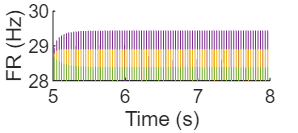

filepath = '../../paper/figure4/';
pop = 1;
figure();

hold on;
 
% recX = [1 4 4 1];
% recY = [0 0 200 200];
% r1 = fill(recX, recY, 0.9*[209 211 212]/256,'LineStyle','none');
% alpha(r1,0.5);

% plot(timeax,squeeze(r(pop,:,4)),'r','LineWidth',0.3);
% plot(timeax,squeeze(r(pop,:,5)),'b','LineWidth',0.3);

plot(timeax,squeeze(r(pop,:,4)),'Color','#7E2F8E','LineWidth',0.3);
plot(timeax,squeeze(r(pop,:,3)),'Color','#EDB120','LineWidth',0.3);
plot(timeax,squeeze(r(pop,:,5)),'Color','#77AC30','LineWidth',0.3);

hold off;
axis([stimIn/1000 (time-1000)/1000 28 30]);
xlabel("Time (s)");
ylabel("FR (Hz)");
xticks([5 6 7 8]);

x0 = 0; y0 = 0; width = 4.5; height = 2;
set(gcf,'units','centimeters','position',[x0,y0,width,height]);
set(gca, 'FontName', 'Arial');
set(gca,'FontSize',8);
filename = append(filepath,'tc_sq_L23E');
print(filename, '-dpng', '-r600');
print(filename, '-dsvg', '-r600');

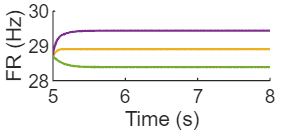

figure();

hold on;

% recX = [1 4 4 1];
% recY = [0 0 200 200];
% r1 = fill(recX, recY, 0.9*[209 211 212]/256,'LineStyle','none');
% alpha(r1,0.5);

envMthd = 'peak';
envWdo = 4000;
% [cond4BF, ] = envelope(squeeze(r(pop,1:step_stimIn,4)),envWdo,envMthd);
% [cond5BF, ] = envelope(squeeze(r(pop,1:step_stimIn,5)),envWdo,envMthd);
% 
% [cond4AF, ] = envelope(squeeze(r(pop,step_stimIn+1:step_stimIn+step_stim+1,4)),envWdo,envMthd);
% [cond5AF, ] = envelope(squeeze(r(pop,step_stimIn+1:step_stimIn+step_stim+1,5)),envWdo,envMthd);
% 
% cond4 = cat(2, cond4BF, cond4AF);
% cond5 = cat(2, cond5BF, cond5AF);
% 
% plot(timeax,cond4,'r','LineWidth',1);
% plot(timeax,cond5,'b','LineWidth',1);

[cond1BF, ] = envelope(squeeze(r(pop,1:step_stimIn,1)),envWdo,envMthd);
[cond2BF, ] = envelope(squeeze(r(pop,1:step_stimIn,2)),envWdo,envMthd);
[cond3BF, ] = envelope(squeeze(r(pop,1:step_stimIn,3)),envWdo,envMthd);
[cond4BF, ] = envelope(squeeze(r(pop,1:step_stimIn,4)),envWdo,envMthd);
[cond5BF, ] = envelope(squeeze(r(pop,1:step_stimIn,5)),envWdo,envMthd);

[cond1AF, ] = envelope(squeeze(r(pop,step_stimIn+1:step_stimIn+step_stim+1,1)),envWdo,envMthd);
[cond2AF, ] = envelope(squeeze(r(pop,step_stimIn+1:step_stimIn+step_stim+1,2)),envWdo,envMthd);
[cond3AF, ] = envelope(squeeze(r(pop,step_stimIn+1:step_stimIn+step_stim+1,3)),envWdo,envMthd);
[cond4AF, ] = envelope(squeeze(r(pop,step_stimIn+1:step_stimIn+step_stim+1,4)),envWdo,envMthd);
[cond5AF, ] = envelope(squeeze(r(pop,step_stimIn+1:step_stimIn+step_stim+1,5)),envWdo,envMthd);

cond1 = cat(2, cond1BF, cond1AF);
cond2 = cat(2, cond2BF, cond2AF);
cond3 = cat(2, cond3BF, cond3AF);
cond4 = cat(2, cond4BF, cond4AF);
cond5 = cat(2, cond5BF, cond5AF);


plot(timeax,cond3,'Color','#EDB120','LineWidth',1);
plot(timeax,cond4,'Color','#7E2F8E','LineWidth',1);
plot(timeax,cond5,'Color','#77AC30','LineWidth',1);

hold off;
axis([stimIn/1000 (time-1000)/1000 28 30]);
xlabel("Time (s)");
ylabel("FR (Hz)");
xticks([5 6 7 8]);

x0 = 0; y0 = 0; width = 4.5; height = 2;
set(gcf,'units','centimeters','position',[x0,y0,width,height]);
set(gca, 'FontName', 'Arial');
set(gca,'FontSize',8);
filename = append(filepath,'tc_sq_L23E_env');
print(filename, '-dpng', '-r600');
print(filename, '-dsvg', '-r600');

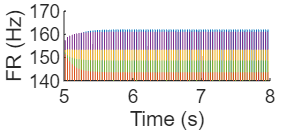

pop = 5;
figure();

hold on;
 
% recX = [1 4 4 1];
% recY = [0 0 200 200];
% r1 = fill(recX, recY, 0.9*[209 211 212]/256,'LineStyle','none');
% alpha(r1,0.5);

plot(timeax,squeeze(r(pop,:,1)),'Color','#0072BD','LineWidth',0.3);
plot(timeax,squeeze(r(pop,:,4)),'Color','#7E2F8E','LineWidth',0.3);
plot(timeax,squeeze(r(pop,:,3)),'Color','#EDB120','LineWidth',0.3);
plot(timeax,squeeze(r(pop,:,5)),'Color','#77AC30','LineWidth',0.3);
plot(timeax,squeeze(r(pop,:,2)),'Color','#D95319','LineWidth',0.3);

hold off;
axis([stimIn/1000 (time-1000)/1000 140 170]);
xlabel("Time (s)");
ylabel("FR (Hz)");
xticks([5 6 7 8]);

x0 = 0; y0 = 0; width = 4.5; height = 2;
set(gcf,'units','centimeters','position',[x0,y0,width,height]);
set(gca, 'FontName', 'Arial');
set(gca,'FontSize',8);
filename = append(filepath,'tc_sq_L5E');
print(filename, '-dpng', '-r600');
print(filename, '-dsvg', '-r600');

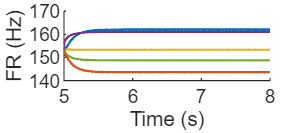

figure();

hold on;

% recX = [1 4 4 1];
% recY = [0 0 200 200];
% r1 = fill(recX, recY, 0.9*[209 211 212]/256,'LineStyle','none');
% alpha(r1,0.5);

envMthd = 'peak';
envWdo = 4000;
[cond1BF, ] = envelope(squeeze(r(pop,1:step_stimIn,1)),envWdo,envMthd);
[cond2BF, ] = envelope(squeeze(r(pop,1:step_stimIn,2)),envWdo,envMthd);
[cond3BF, ] = envelope(squeeze(r(pop,1:step_stimIn,3)),envWdo,envMthd);
[cond4BF, ] = envelope(squeeze(r(pop,1:step_stimIn,4)),envWdo,envMthd);
[cond5BF, ] = envelope(squeeze(r(pop,1:step_stimIn,5)),envWdo,envMthd);

[cond1AF, ] = envelope(squeeze(r(pop,step_stimIn+1:step_stimIn+step_stim+1,1)),envWdo,envMthd);
[cond2AF, ] = envelope(squeeze(r(pop,step_stimIn+1:step_stimIn+step_stim+1,2)),envWdo,envMthd);
[cond3AF, ] = envelope(squeeze(r(pop,step_stimIn+1:step_stimIn+step_stim+1,3)),envWdo,envMthd);
[cond4AF, ] = envelope(squeeze(r(pop,step_stimIn+1:step_stimIn+step_stim+1,4)),envWdo,envMthd);
[cond5AF, ] = envelope(squeeze(r(pop,step_stimIn+1:step_stimIn+step_stim+1,5)),envWdo,envMthd);

cond1 = cat(2, cond1BF, cond1AF);
cond2 = cat(2, cond2BF, cond2AF);
cond3 = cat(2, cond3BF, cond3AF);
cond4 = cat(2, cond4BF, cond4AF);
cond5 = cat(2, cond5BF, cond5AF);

plot(timeax,cond1,'Color','#0072BD','LineWidth',1);
plot(timeax,cond3,'Color','#EDB120','LineWidth',1);
plot(timeax,cond4,'Color','#7E2F8E','LineWidth',1);
plot(timeax,cond5,'Color','#77AC30','LineWidth',1);
plot(timeax,cond2,'Color','#D95319','LineWidth',1);

hold off;
axis([stimIn/1000 (time-1000)/1000 140 170]);
xlabel("Time (s)");
ylabel("FR (Hz)");
xticks([5 6 7 8]);

x0 = 0; y0 = 0; width = 4.5; height = 2;
set(gcf,'units','centimeters','position',[x0,y0,width,height]);
set(gca, 'FontName', 'Arial');
set(gca,'FontSize',8);
filename = append(filepath,'tc_sq_L5E_env');
print(filename, '-dpng', '-r600');
print(filename, '-dsvg', '-r600');

## Line chart: square

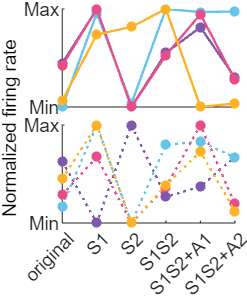

filepath = '../../paper/figure5/';
figure();
[~,~,~,~,~,level,~] = record(r/1000, time);
level_norm = normBetween01(level,2);
condax = [0 1 2 3 4 5];
dot_size = 15;

level_norm(7,6) = level_norm(7,6)*3; % diff up
% Create a subplot for the upper half
subplot(2, 1, 1); 
hold on;
for layer = 1:4
    pop_E = (layer-1)*2 + 1;
    plot(condax, level_norm(pop_E,:),'Color',solidColors(layer,:), 'LineWidth',1);
    scatter(condax, level_norm(pop_E,:), dot_size,...
        'MarkerEdgeColor', dotColors(layer,:), 'MarkerFaceColor',dotColors(layer,:));
end
xlim([0 5]);
xticks([]); % No xticks for the upper plot
ylim([0 1]);
yticks([0 1]);
yticklabels(["Min" "Max"]);
set(gca, 'FontName', 'Arial');
set(gca,'FontSize',8);
set(gca, 'Position', [0.25 0.64 0.7 0.33]); % Adjust the position manually

% Create a subplot for the lower half
subplot(2, 1, 2); 
hold on;
for layer = 1:4
    pop_I = layer*2;
    plot(condax, level_norm(pop_I,:),":",'Color',dashColors(layer,:), 'LineWidth',1);
    scatter(condax, level_norm(pop_I,:), dot_size,...
        'MarkerEdgeColor', dotColors(layer,:), 'MarkerFaceColor',dotColors(layer,:));
end
xlabel("Conditions");
xlim([0 5]);
xticks([0 1 2 3 4 5]);
xticklabels(["original" "S1" "S2" "S1S2" "S1S2+A1" "S1S2+A2"]);
ylim([0 1]);
yticks([0 1]);
yticklabels(["Min" "Max"]);
set(gca, 'FontName', 'Arial');
set(gca,'FontSize',8);
set(gca, 'Position', [0.25 0.25 0.7 0.33]); % Adjust the position manually

% Add y label to the figure using annotation
annotation('textbox', [0.2, 0.2, 0.9, 0.2], 'String', 'Normalized firing rate',...
    'HorizontalAlignment', 'center', 'Rotation', 90, 'FontSize', 8, 'FontName', 'Arial',...
    'EdgeColor', 'none');

x0 = 0; y0 = 0; width = 4.5*(106/128); height = 4.5;
set(gcf,'units','centimeters','position',[x0,y0,width,height]);
set(gca, 'FontName', 'Arial');
set(gca,'FontSize',8);

filename = append(filepath,'tc_sq_lChart');
print(filename, '-dpng', '-r600');
print(filename, '-dsvg', '-r600');

## Time-course: Triangle

Delta_E = 0.46;
Delta_I = 0.045;

[r,~,~] = once(Delta_E, Delta_I, Iattn, time, stimIn);
r = r*1000;

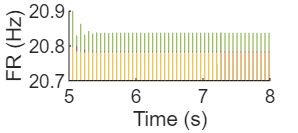

filepath = '../../paper/figure4/';
pop = 1;
figure();

hold on;
 
% recX = [1 4 4 1];
% recY = [0 0 200 200];
% r1 = fill(recX, recY, 0.9*[209 211 212]/256,'LineStyle','none');
% alpha(r1,0.5);

% plot(timeax,squeeze(r(pop,:,5)),'b','LineWidth',0.3);
% plot(timeax,squeeze(r(pop,:,4)),'r','LineWidth',0.3);

plot(timeax,squeeze(r(pop,:,5)),'Color','#77AC30','LineWidth',0.3);
plot(timeax,squeeze(r(pop,:,4)),'Color','#7E2F8E','LineWidth',0.3);
plot(timeax,squeeze(r(pop,:,3)),'Color','#EDB120','LineWidth',0.3);

hold off;
axis([stimIn/1000 (time-1000)/1000 20.7 20.9]);
xlabel("Time (s)");
ylabel("FR (Hz)");
xticks([5 6 7 8]);

x0 = 0; y0 = 0; width = 4.5; height = 2;
set(gcf,'units','centimeters','position',[x0,y0,width,height]);
set(gca, 'FontName', 'Arial');
set(gca,'FontSize',8);
filename = append(filepath,'tc_tri_L23E');
print(filename, '-dpng', '-r600');
print(filename, '-dsvg', '-r600');

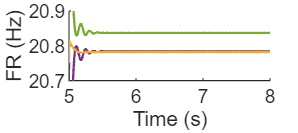

figure();

hold on;

% recX = [1 4 4 1];
% recY = [0 0 200 200];
% r1 = fill(recX, recY, 0.9*[209 211 212]/256,'LineStyle','none');
% alpha(r1,0.5);

envMthd = 'peak';
envWdo = 4000;
% [cond4BF, ] = envelope(squeeze(r(pop,1:step_stimIn,4)),envWdo,envMthd);
% [cond5BF, ] = envelope(squeeze(r(pop,1:step_stimIn,5)),envWdo,envMthd);
% 
% [cond4AF, ] = envelope(squeeze(r(pop,step_stimIn+1:step_stimIn+step_stim+1,4)),envWdo,envMthd);
% [cond5AF, ] = envelope(squeeze(r(pop,step_stimIn+1:step_stimIn+step_stim+1,5)),envWdo,envMthd);
% 
% cond4 = cat(2, cond4BF, cond4AF);
% cond5 = cat(2, cond5BF, cond5AF);
% 
% plot(timeax,cond4,'r','LineWidth',1);
% plot(timeax,cond5,'b','LineWidth',1);

[cond1BF, ] = envelope(squeeze(r(pop,1:step_stimIn,1)),envWdo,envMthd);
[cond2BF, ] = envelope(squeeze(r(pop,1:step_stimIn,2)),envWdo,envMthd);
[cond3BF, ] = envelope(squeeze(r(pop,1:step_stimIn,3)),envWdo,envMthd);
[cond4BF, ] = envelope(squeeze(r(pop,1:step_stimIn,4)),envWdo,envMthd);
[cond5BF, ] = envelope(squeeze(r(pop,1:step_stimIn,5)),envWdo,envMthd);

[cond1AF, ] = envelope(squeeze(r(pop,step_stimIn+1:step_stimIn+step_stim+1,1)),envWdo,envMthd);
[cond2AF, ] = envelope(squeeze(r(pop,step_stimIn+1:step_stimIn+step_stim+1,2)),envWdo,envMthd);
[cond3AF, ] = envelope(squeeze(r(pop,step_stimIn+1:step_stimIn+step_stim+1,3)),envWdo,envMthd);
[cond4AF, ] = envelope(squeeze(r(pop,step_stimIn+1:step_stimIn+step_stim+1,4)),envWdo,envMthd);
[cond5AF, ] = envelope(squeeze(r(pop,step_stimIn+1:step_stimIn+step_stim+1,5)),envWdo,envMthd);

cond1 = cat(2, cond1BF, cond1AF);
cond2 = cat(2, cond2BF, cond2AF);
cond3 = cat(2, cond3BF, cond3AF);
cond4 = cat(2, cond4BF, cond4AF);
cond5 = cat(2, cond5BF, cond5AF);

plot(timeax,cond5,'Color','#77AC30','LineWidth',1);
plot(timeax,cond4,'Color','#7E2F8E','LineWidth',1);
plot(timeax,cond3,'Color','#EDB120','LineWidth',1);

hold off;
axis([stimIn/1000 (time-1000)/1000 20.7 20.9]);
xlabel("Time (s)");
ylabel("FR (Hz)");
xticks([5 6 7 8]);

x0 = 0; y0 = 0; width = 4.5; height = 2;
set(gcf,'units','centimeters','position',[x0,y0,width,height]);
set(gca, 'FontName', 'Arial');
set(gca,'FontSize',8);
filename = append(filepath,'tc_tri_L23E_env');
print(filename, '-dpng', '-r600');
print(filename, '-dsvg', '-r600');

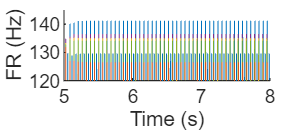

pop = 5;
figure();

hold on;
 
% recX = [1 4 4 1];
% recY = [0 0 200 200];
% r1 = fill(recX, recY, 0.9*[209 211 212]/256,'LineStyle','none');
% alpha(r1,0.5);

plot(timeax,squeeze(r(pop,:,1)),'Color','#0072BD','LineWidth',0.3);
plot(timeax,squeeze(r(pop,:,4)),'Color','#7E2F8E','LineWidth',0.3);
plot(timeax,squeeze(r(pop,:,3)),'Color','#EDB120','LineWidth',0.3);
plot(timeax,squeeze(r(pop,:,5)),'Color','#77AC30','LineWidth',0.3);
plot(timeax,squeeze(r(pop,:,2)),'Color','#D95319','LineWidth',0.3);

hold off;
axis([stimIn/1000 (time-1000)/1000 120 145]);
xlabel("Time (s)");
ylabel("FR (Hz)");
xticks([5 6 7 8]);

x0 = 0; y0 = 0; width = 4.5; height = 2;
set(gcf,'units','centimeters','position',[x0,y0,width,height]);
set(gca, 'FontName', 'Arial');
set(gca,'FontSize',8);
filename = append(filepath,'tc_tri_L5E');
print(filename, '-dpng', '-r600');
print(filename, '-dsvg', '-r600');

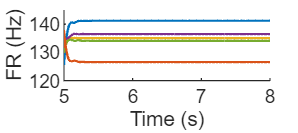

figure();

hold on;

% recX = [1 4 4 1];
% recY = [0 0 200 200];
% r1 = fill(recX, recY, 0.9*[209 211 212]/256,'LineStyle','none');
% alpha(r1,0.5);

envMthd = 'peak';
envWdo = 4000;
[cond1BF, ] = envelope(squeeze(r(pop,1:step_stimIn,1)),envWdo,envMthd);
[cond2BF, ] = envelope(squeeze(r(pop,1:step_stimIn,2)),envWdo,envMthd);
[cond3BF, ] = envelope(squeeze(r(pop,1:step_stimIn,3)),envWdo,envMthd);
[cond4BF, ] = envelope(squeeze(r(pop,1:step_stimIn,4)),envWdo,envMthd);
[cond5BF, ] = envelope(squeeze(r(pop,1:step_stimIn,5)),envWdo,envMthd);

[cond1AF, ] = envelope(squeeze(r(pop,step_stimIn+1:step_stimIn+step_stim+1,1)),envWdo,envMthd);
[cond2AF, ] = envelope(squeeze(r(pop,step_stimIn+1:step_stimIn+step_stim+1,2)),envWdo,envMthd);
[cond3AF, ] = envelope(squeeze(r(pop,step_stimIn+1:step_stimIn+step_stim+1,3)),envWdo,envMthd);
[cond4AF, ] = envelope(squeeze(r(pop,step_stimIn+1:step_stimIn+step_stim+1,4)),envWdo,envMthd);
[cond5AF, ] = envelope(squeeze(r(pop,step_stimIn+1:step_stimIn+step_stim+1,5)),envWdo,envMthd);

cond1 = cat(2, cond1BF, cond1AF);
cond2 = cat(2, cond2BF, cond2AF);
cond3 = cat(2, cond3BF, cond3AF);
cond4 = cat(2, cond4BF, cond4AF);
cond5 = cat(2, cond5BF, cond5AF);

plot(timeax,cond1,'Color','#0072BD','LineWidth',1);
plot(timeax,cond3,'Color','#EDB120','LineWidth',1);
plot(timeax,cond4,'Color','#7E2F8E','LineWidth',1);
plot(timeax,cond5,'Color','#77AC30','LineWidth',1);
plot(timeax,cond2,'Color','#D95319','LineWidth',1);

hold off;
axis([stimIn/1000 (time-1000)/1000 120 145]);
xlabel("Time (s)");
ylabel("FR (Hz)");
xticks([5 6 7 8]);

x0 = 0; y0 = 0; width = 4.5; height = 2;
set(gcf,'units','centimeters','position',[x0,y0,width,height]);
set(gca, 'FontName', 'Arial');
set(gca,'FontSize',8);
filename = append(filepath,'tc_tri_L5E_env');
print(filename, '-dpng', '-r600');
print(filename, '-dsvg', '-r600');

## Line chart: triangle

% figure();
% [~,~,~,~,~,level,~] = record(r/1000, time);
% level_norm = normBetween01(level,2);
% condax = [0 1 2 3 4 5];
% for layer = 1:4
%     pop_E = (layer-1)*2 + 1;
%     pop_I = layer*2;
% 
%     plot(condax, level_norm(pop_E,:),'Color',solidColors(layer,:), 'LineWidth',1);
%     hold on;
%     plot(condax, level_norm(pop_I,:),":",'Color',dashColors(layer,:), 'LineWidth',1);
% 
% end
% 
% ylabel("Normalized firing rate");
% % xlabel("Conditions");
% xlim([0 5]);xticks([0 1 2 3 4 5]);
% xticklabels(["original" "S1" "S2" "S1S2" "S1S2+A1" "S1S2+A2"]);
% ylim([-0.1 1.1]);
% yticks([0 1]);
% yticklabels(["Min" "Max"]);
% 
% x0 = 0; y0 = 0; width = 4.5; height = 4.5;
% set(gcf,'units','centimeters','position',[x0,y0,width,height]);
% set(gca, 'FontName', 'Arial');
% set(gca,'FontSize',8);
% 
% filename = append(filepath,'tc_tri_lChart');
% print(filename, '-dpng', '-r600');
% print(filename, '-dsvg', '-r600');

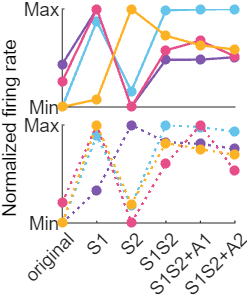

filepath = '../../paper/figure5/';
figure();
[~,~,~,~,~,level,~] = record(r/1000, time);
level_norm = normBetween01(level,2);
condax = [0 1 2 3 4 5];
dot_size = 15;

level_norm(7,6) = level_norm(7,6)*0.95; % diff down
% Create a subplot for the upper half
subplot(2, 1, 1); 
hold on;
for layer = 1:4
    pop_E = (layer-1)*2 + 1;
    plot(condax, level_norm(pop_E,:),'Color',solidColors(layer,:), 'LineWidth',1);
    scatter(condax, level_norm(pop_E,:), dot_size,...
        'MarkerEdgeColor', dotColors(layer,:), 'MarkerFaceColor',dotColors(layer,:));
end
xlim([0 5]);
xticks([]); % No xticks for the upper plot
ylim([0 1]);
yticks([0 1]);
yticklabels(["Min" "Max"]);
set(gca, 'FontName', 'Arial');
set(gca,'FontSize',8);
set(gca, 'Position', [0.25 0.64 0.7 0.33]); % Adjust the position manually

% Create a subplot for the lower half
subplot(2, 1, 2); 
hold on;
for layer = 1:4
    pop_I = layer*2;
    plot(condax, level_norm(pop_I,:),":",'Color',dashColors(layer,:), 'LineWidth',1);
    scatter(condax, level_norm(pop_I,:), dot_size,...
        'MarkerEdgeColor', dotColors(layer,:), 'MarkerFaceColor',dotColors(layer,:));
end
xlabel("Conditions");
xlim([0 5]);
xticks([0 1 2 3 4 5]);
xticklabels(["original" "S1" "S2" "S1S2" "S1S2+A1" "S1S2+A2"]);
ylim([0 1]);
yticks([0 1]);
yticklabels(["Min" "Max"]);
set(gca, 'FontName', 'Arial');
set(gca,'FontSize',8);
set(gca, 'Position', [0.25 0.25 0.7 0.33]); % Adjust the position manually

% Add y label to the figure using annotation
annotation('textbox', [0.2, 0.2, 0.9, 0.2], 'String', 'Normalized firing rate',...
    'HorizontalAlignment', 'center', 'Rotation', 90, 'FontSize', 8, 'FontName', 'Arial',...
    'EdgeColor', 'none');

x0 = 0; y0 = 0; width = 4.5*(106/128); height = 4.5;
set(gcf,'units','centimeters','position',[x0,y0,width,height]);
set(gca, 'FontName', 'Arial');
set(gca,'FontSize',8);

filename = append(filepath,'tc_tri_lChart');
print(filename, '-dpng', '-r600');
print(filename, '-dsvg', '-r600');